## **EEGLAB OpenNeuro to DL pipeline**

In this example, we present the pipeline that downloads the [EEG dataset](https://openneuro.org/datasets/ds003061/versions/1.1.2) from [OpenNeuro](https://docs.openneuro.org/user_guide.html) archive [1], pre-processes it using [EEGLAB](https://sccn.ucsd.edu/eeglab/index.php) toolbox [2] and formats as input for deep learning-based classification. The data was collected at the Meditation Research Institute (MRI) in Rishikesh, India under the supervision of Arnaud Delorme, PhD ([Swartz Center for Computational Neuroscience](https://sccn.ucsd.edu/)). The data is stored in a [BIDS](https://bids.neuroimaging.io/) format [3], a standard defining the organization of neuroimaging/accompanying behavioral data, as well as the relevant metadata, facilitating the data sharing and reproducibility.

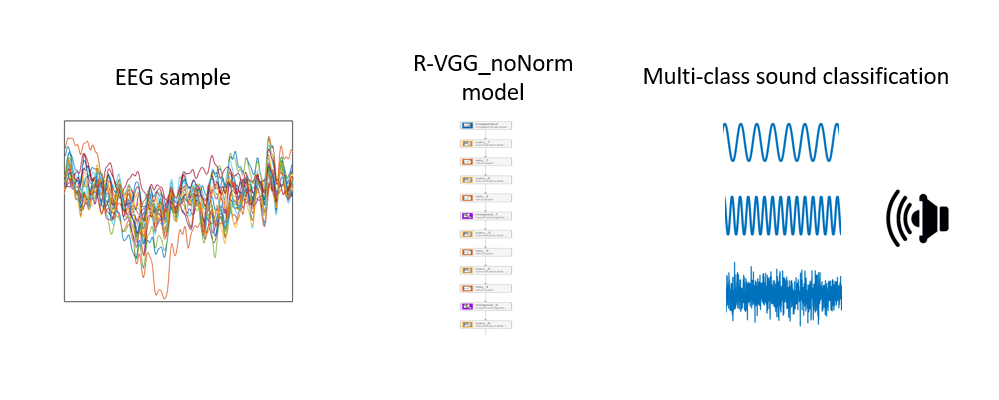

**Background on Dataset**

The dataset consists of a scalp EEG recordings from 13 participants, each providing 3 13-min sessions. Participants were asked to keep the eyes closed during recording, while being presented with 750 **auditory stimuli**, divided in 3 groups: **standard **(500 Hz pure tone lasting 60 ms), **oddball** (1000 Hz pure tone lasting 60 ms) and **distractors** (white noise lasting 60 ms). Sounds were presented at 1/sec rate. Participants were instructed to respond to oddball tone using a key press. 

Recording was performed using the standard [**10-20 EEG system**](https://en.wikipedia.org/wiki/10%E2%80%9320_system_(EEG)) (Active Two Biosemi system, Biosemi Inc.), with 1024 Hz sampling rate. The data in OpenNeuro dataset was subsequently resampled at 256 Hz. Individual samples consist of 1 sec signal across 144 channels, spanning the time window between the two consecutive tone onsets.

**Background on Example**

In this example, we are demonstrating the multi-class (more than two classes) classification of auditory stimuli based on the scalp EEG recordings. For each stimulus, the time window of 0-0.5 sec relative to stimulus onset is used for model training/inference. 

**BIDS Format**

BIDS format [3] defines the dataset structure and minimum information the dataset needs to contain. The EEG data files could be stored as one of the standard EEG formats (e.g. edf, EEGLAB, NWB). The EEG files in this dataset are stored in *.set format, produced by EEGLAB toolbox. The EEGLAB `pop_importbids` function downloads the BIDS dataset from the online repository and puts it in the EEGLAB format. 


% 
curr_env = getenv; %checking if it's running on MATLAB Online or locally

if isKey(curr_env,"MW_DDUX_APP_NAME")==1 & curr_env("MW_DDUX_APP_NAME")=='MATLAB_ONLINE'
    environment = 'online';
elseif isKey(curr_env,"MW_DDUX_APP_NAME")==0
    environment = 'local';
end

if strcmp(environment, 'online')==1
    addpath MATLAB Add-Ons/Collections/EEGLAB;
    addpath '/MATLAB Drive/Repositories/study_ml';
else
    if exist('eeglab','dir')==1
        eeglab;
    elseif exist('eeglab','dir')==7
        curr_dir = pwd;
        addpath(sprintf('%s/eeglab',curr_dir));
        eeglab;
    else
        curr_dir = pwd;
        gitclone('https://github.com/sccn/eeglab');
        addpath(sprintf('%s/eeglab',curr_dir));
        eeglab;
    end
end


%fullfile to build path to work on Linux


%
%two different scripts, one to prepare the data, one to run the model
%
% Build the path of the selected dataset
base_dir = pwd;

Events file detected! Epochs will be generated with [0, 0.5] s time window 
pop_epoch():863 epochs selected
Epoching...
pop_epoch():863 epochs generated
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity


eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-001_task-P300_run-1_eeg.set segments (n=863):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-001_task-P300_run-2_eeg.set segments (n=861):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-001_task-P300_run-3_eeg.set segments (n=859):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_task-P300_run-1_eeg.set segments (n=811):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_task-P300_run-2_eeg.set segments (n=807):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-002_task-P300_run-3_eeg.set segments (n=799):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_task-P300_run-1_eeg.set segments (n=860):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_task-P300_run-2_eeg.set segments (n=859):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-003_task-P300_run-3_eeg.set segments (n=861):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_task-P300_run-1_eeg.set segments (n=859):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_task-P300_run-2_eeg.set segments (n=856):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-004_task-P300_run-3_eeg.set segments (n=860):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-005_task-P300_run-1_eeg.set segments (n=859):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-005_task-P300_run-2_eeg.set segments (n=861):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-005_task-P300_run-3_eeg.set segments (n=856):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-006_task-P300_run-1_eeg.set segments (n=855):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-006_task-P300_run-2_eeg.set segments (n=835):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-006_task-P300_run-3_eeg.set segments (n=859):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-007_task-P300_run-1_eeg.set segments (n=862):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-007_task-P300_run-2_eeg.set segments (n=849):........................

eeg_uniformepochinfo: found empty values for field 'duration' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'sample' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'trial_type' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'response_time' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'stim_file' for 0 epochs
                      filling with values of other events in the same epochs
eeg_uniformepochinfo: found empty values for field 'urevent' for 0 epochs
                      filling with values of other events in the same epochs
Exporting sub-007_task-P300_run-3_eeg.set segments (n=856):........................

Out of memory.

Error in epoch (line 161)
epochdat(:,:,find(indexes == 0)) = [];

Error in pop_epoch (line 351)
 case 'points',	[EEG.data, tmptime, indices, epochevent]= epoch(EEG.data, alllatencies, [lim(1) lim(2)]*EEG.srate, ...

Error in 

dataset_ID = 'ds003061';
filePath = sprintf('%s/%s',base_dir,dataset_ID);
mkdir(filePath);
tic
status = copyfile('s3://openneuro.org/ds003061', filePath); %make it work on Linux
toc%this part takes about 2.5 min
%


out_dir = sprintf('%s/DL',base_dir);
tic
[STUDY, ALLEEG] = pop_importbids(filePath, 'eventtype', 'value', 'outputdir', out_dir);
toc%this also takes about 2.5 min

Unrecognized function or variable 'stimulus_type_num'.


rmdir(filePath, 's');%put this inside the function and use the environment input argument

The pop_importbids function provides two outputs, **STUDY** (the EEGLAB structure defining the group analysis parameters) and **ALLEEG** (the structure containing all the loaded EEG datasets). 

**ALLEEG** is a structure with the first dimension equaling the number of loaded dataset.

- ALLEEG.**filename** - contains the filenames

- ALLEEG.**subject** - subject labels

- ALLEEG.**chanlocs** - channel labels and respective anatomical coordinates

- ALLEEG.**event** - information on trial timestamps and presented stimuli

- ALLEEG.**data** - EEG time series, organized as a matrix (n of channels x n of samples)

**Exploring the Dataset **

We can check the number of datasets and unique subjects.

dataset_info(ALLEEG);

### **Data visualization**

Next, we can plot the EEG trace from an example channel, e.g. the first channel from the first dataset.

example_eeg_trace = ALLEEG(1).data(1,:);

Sample size = 8, 8, 128



figure;plot(example_eeg_trace); xlim([1 numel(example_eeg_trace)]); xlabel('n of samples'); 
ylim([min(example_eeg_trace) max(example_eeg_trace)]); ylabel('voltage'); title(sprintf('%s',ALLEEG(1).chanlocs(1).labels))

We can see the slow voltage change (drift) across the recording time window, due to accumulation of charge on electrode contacts. This hugely increases the range of DL model input values, which could interfere with the DL training. For the more detailed discussion on the influence of input range on DL model training, check here. 

### **Highpass filtering**

To alleviate this problem, we can apply highpass filtering, one of the commonly used steps in EEG preprocessing. The `highpassfilt.m` helper function performs this step.

classProportions =     0.1344    0.1382    0.7274


uniqueLabels = 3×1 cell array
    {'oddball_with_reponse'}
    {'response'            }
    {'standard'            }


figure;plot(example_eeg_trace); xlim([1 numel(example_eeg_trace)]); xlabel('n of samples'); 
ylim([min(example_eeg_trace) max(example_eeg_trace)]); ylabel('voltage'); title(sprintf('%s',ALLEEG(1).chanlocs(1).labels))

We can see that the highpass filtering removed the slow voltage drift, resulting in a much narrower range of values fed into the DL model.

## Preparing the data for DL training/inference format

`pop_studydl` EEGLAB function resamples the EEG signals stored in EEGLAB structure down to 128 Hz and exports it into ML/DL data format.

tic

ans = "balanced"

%pop_studydl_v2(STUDY, ALLEEG, 'outputdir', fullfile(base_dir, 'ML_EXPORT'));
if strcmp(environment,'local')==1
[ALLEEG] = pop_studydl_integrated(STUDY, ALLEEG,'outputdir', fullfile(base_dir, 'ML_EXPORT'),'environment', environment);
elseif strcmp(environment,'online')==1
[ALLEEG, varargout] = pop_studydl_integrated(STUDY, ALLEEG, environment, 'outputdir', fullfile(base_dir, 'ML_EXPORT'));
end
toc


classProportions =     0.3364    0.3481    0.3154


uniqueLabels = 3×1 cell array
    {'oddball_with_reponse'}
    {'response'            }
    {'standard'            }


## Assigning the labels

selected_labels = {'standard', 'oddball_with_reponse', 'response'}; %the classification task will include the 3 selected classes

ans = "subjects_separated"


if strcmp(environment,'local')==1
    [ds] = create_datastore(base_dir, selected_labels, environment);
elseif strcmp(environment,'online')==1
    [ds] = create_datastore(base_dir, selected_labels, environment, stimulus_type_num, samples_all, sample_ID_all);
end


## Preview the first sample of the datastore

sample = preview(ds);
fprintf('Sample size = %d, %d, %d\n', size(sample));

## Compute class weights if classes are imbalanced

In real life data, classes are often **imbalanced**. The class imbalance is defined as the skewed proportions of individual class samples, which could affect the model training and bias the inference towards the **majority class** (the class with largest proportion of samples). Here is a more detailed [explanation](https://medium.com/nerd-for-tech/class-imbalance-problem-and-ways-to-handle-it-4861a195398a) on the influence of class imbalance on model performance. One of the possible options to deal with the class imbalance is assigning the **class weights, **which set the relative importance of individual classes in training. Class weights are computed by the `compute_class_weights` helper function.

[classProportions, uniqueLabels] = compute_class_proportions(ds,environment)

**Creating the Balanced Dataset**

One way of improving the model performance would be to provide the balanced dataset, where the proportions of different classes are approximately equal. The `create_balanced_dataset` helper function performs this step, by dropping the subset of majority class samples. 

In the drop-down menu below, you can indicate whether to use the **balanced** or **original** dataset.

"balanced"

dataset = ans; 

if strcmp(dataset,'original')==1
    [classProportions, uniqueLabels] = compute_class_proportions(train_ds, environment)
elseif strcmp(dataset,'balanced')==1
    [train_ds test_ds val_ds] = create_balanced_dataset(train_ds, test_ds, val_ds, environment);
    [classProportions, uniqueLabels] = compute_class_proportions(train_ds, environment)
end

Finally, we can split the datastore and evaluate the model performance. Splitting could be done so the training, testing and validation sets all contain the samples from all subjects or the different subjects. The choice can be indicated in the drop-down menu below.

"subjects_separated"
splitting_mode = ans;

[train_ds, test_ds, val_ds] = split_datastore(ds, splitting_mode, environment, selected_labels, base_dir);


## Constructing & Training Network

Here we construct a modified VGG model, which is a simple to understand yet powerfull deep learning model [4]. This model represents a convolutional neural network with 27 layers, with the input layer (`imageInputLayer`) corresponding to the individual sample dimensions and the output layer (`classificationLayer`) reflecting the number of class labels (1 x 2). A detailed explanation of the concept of convolutional neural networks and an overview of individual components (layers, activation functions etc.) may be found [here](https://en.wikipedia.org/wiki/Convolutional_neural_network).

MATLAB `classificationLayer` function, which constructs the neural network **classification output layer**, provides the optional parameter classWeights to account for class weights in training process. 


%eeg_regepochs
%%Task’, { ‘ec’ ‘eo’ }
% labels in table, with other info
%create training. testing without subject overlap
%add option to ignore subject labels, keep the subject separate

if strcmp(environment,'local')==1
    classes = unique(train_ds.Labels);
elseif strcmp(environment,'online')==1
    classes = unique(train_ds.Labels);
end
    num_labels = numel(classes);

    sample_size = size(preview(ds));


layers = [
    imageInputLayer(sample_size,"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],16,"Name","conv1","Padding",[1 1 1 1],"WeightL2Factor",0)

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:30 |       42.50% |       32.74% |       1.0433 |       1.2047 |          0.0005 |
|       1 |          50 |       00:00:56 |       40.00% |       60.88% |       1.0500 |       0.9440 |          0.0005 |
|       1 |         100 |       00:01:15 |       52.50% |       59.37% |       1.0165 |       0.8796 |          0.0005 |
|       1 |         150 |       00:01:36 |       57.50% |       61.95% |       0.9405 |       0.8836 |          0.0005 |
|       

    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],16,"Name","conv2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],32,"Name","conv4","Padding",[1 1 1 1],"WeightL2Factor",0)

Percent correct training   is 82.32 %


    reluLayer("Name","relu2_2")

Percent correct validation is 68.97 %


    maxPooling2dLayer([2 2],"Name","pool2","Padding","same","Stride",[2 2])

Percent correct testing    is 67.40 %


    convolution2dLayer([3 3],64,"Name","conv5","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],64,"Name","conv6","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],64,"Name","conv7","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(1024,"Name","fc1","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop1")

classProportions =     0.1345    0.1382    0.7273


uniqueLabels = 3×1 cell array
    {'oddball_with_reponse'}
    {'response'            }
    {'standard'            }


    fullyConnectedLayer(1024,"Name","fc2","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop2")
    fullyConnectedLayer(num_labels,"Name","fc3","WeightL2Factor",0)
    softmaxLayer("Name","prob")
    classificationLayer('Name','classoutput','Classes', classes)]; 

classes = categorical(unique(stimulus_type_train));
image_size = size(samples_all{1});
num_labels = numel(classes);

layers = [
    imageInputLayer(image_size,"Name","imageinput","Normalization","none")
    convolution2dLayer([3 3],16,"Name","conv1","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_1")
    convolution2dLayer([3 3],16,"Name","conv2","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu1_2")
    maxPooling2dLayer([2 2],"Name","pool1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv3","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_1")
    convolution2dLayer([3 3],32,"Name","conv4","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu2_2")
    maxPooling2dLayer([2 2],"Name","pool2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv5","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_1")
    convolution2dLayer([3 3],64,"Name","conv6","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_2")
    convolution2dLayer([3 3],64,"Name","conv7","Padding",[1 1 1 1],"WeightL2Factor",0)
    reluLayer("Name","relu3_3")
    maxPooling2dLayer([2 2],"Name","pool3","Padding","same","Stride",[2 2])
    fullyConnectedLayer(1024,"Name","fc1","WeightL2Factor",0)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop1")
    fullyConnectedLayer(1024,"Name","fc2","WeightL2Factor",0)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop2")
    fullyConnectedLayer(num_labels,"Name","fc3","WeightL2Factor",0)
    softmaxLayer("Name","prob")
    classificationLayer('Name','classoutput','Classes', classes)]; 

Define training settings. There are several [training options](https://in.mathworks.com/help/deeplearning/ref/trainingoptions.html) available. Try different options to improve performance.

maxEpochs = 10;
% disp(sprintf('Training stops at %d epochs, but you can stop manually after epochs',maxEpochs))
% disp('by pressing the STOP button, and the live script can be continued from that point')

options = trainingOptions('adam', ...
    'InitialLearnRate',0.0005, ...
    'SquaredGradientDecayFactor',0.99, ...
    'ValidationData', val_ds, ... the datastore containing validation labels
    'Plots','training-progress',...% allows the real-time monitoring of training progress
    'MaxEpochs',maxEpochs, ...% the n of training epochs. All the samples are presented once during a single epoch.
    'MiniBatchSize',40);

eeg_net = trainNetwork(train_ds,layers,options);

## Testing Trained Network

Finally, classification accuracy is tested against the testing data and expressed as the percentage of correct classifications.

[YPred,err] = classify(eeg_net, train_ds); performance1 = sum(0+ (train_ds.Labels == YPred))/length(YPred);
[YPred,err] = classify(eeg_net, val_ds  ); performance2 = sum(0+ (  val_ds.Labels == YPred))/length(YPred);
[YPred,err] = classify(eeg_net, test_ds ); performance3 = sum(0+ ( test_ds.Labels == YPred))/length(YPred);
fprintf('Percent correct training   is %1.2f %%\n', performance1*100);
fprintf('Percent correct validation is %1.2f %%\n', performance2*100);
fprintf('Percent correct testing    is %1.2f %%\n', performance3*100);

figure;bar(performance2*100);
title('prediction accuracy')
yline(mean(classProportions)*100,'r--','LineWidth',3);
ylabel('prediction accuracy (%)');
xticks([]);yticks([0 50 100]);yticklabels({'0','50','100'});ylim([0 100])
txt = 'chance level';
text(1.6, 5 + mean(classProportions)*100,txt,'Color','r')

 [classProportions, uniqueLabels] = compute_class_proportions(ds_all{i}, environment)
    

**Contributors:**

### **References**

[1] Gorgolewski, K., Esteban, O., Schaefer, G., Wandell, B. and Poldrack, R., 2017. OpenNeuro—a free online platform for sharing and analysis of neuroimaging data. *Organization for human brain mapping. Vancouver, Canada*, *1677*(2).

[2] Delorme, A. and Makeig, S., 2004. EEGLAB: an open source toolbox for analysis of single-trial EEG dynamics including independent component analysis. *Journal of neuroscience methods*, *134*(1), pp.9-21.

[3] Pernet, C.R., Appelhoff, S., Gorgolewski, K.J., Flandin, G., Phillips, C., Delorme, A. and Oostenveld, R., 2019. EEG-BIDS, an extension to the brain imaging data structure for electroencephalography. *Scientific data*, *6*(1), p.103.

### **Helper Functions**

function [ds] = create_datastore(base_dir, selected_labels, environment, varargin)

if strcmp(environment,'local')==1
    
    ds = imageDatastore(fullfile(base_dir, 'ML_EXPORT', 'mat_files'), 'FileExtensions','.mat','IncludeSubfolders',true);

    load_sample = @(x) x.data; 
    readfun = @(x) load_sample(load(x));
    ds.ReadFcn = readfun;
    
    label_info = readtable(fullfile(base_dir,'ML_EXPORT', 'labels_local.csv'));
    label_info_sorted = sortrows(label_info,1);
    label_col = label_info_sorted.Var7; % type of stimulus
    
    
    row_selected = zeros(1,length(label_col), 'logical');
    selected_labels =  {'standard' 'oddball_with_reponse' 'response'};
    
    for iSelected = 1:length(selected_labels)
        inds = strmatch(selected_labels{iSelected}, label_col, 'exact');
        row_selected(inds) = true;
    end
    ds.Files = ds.Files(row_selected);
    ds.Labels = categorical(label_col(row_selected));
    

elseif strcmp(environment,'online')==1

    row_selected = zeros(1,numel(stimulus_type_all), 'logical');
    
    for iSelected = 1:length(selected)
    inds = strmatch(selected{iSelected}, stimulus_type_all, 'exact');
    row_selected(inds) = true;
    end
    
    unique_cat = unique(stimulus_type_all);
    
    for i = 1:numel(unique_cat)
    for ii = 1:numel(stimulus_type_all)
    if strcmp(stimulus_type_all{ii},unique_cat{i})==1
    stimulus_type_num(ii,1) = i;
    end
    end
    end
    
    stimulus_type_num_sel = stimulus_type_num(row_selected);
    samples_all_sel = samples_all(row_selected);
    sample_ID_all_sel = sample_ID_all(row_selected);

    sample_ds = arrayDatastore(samples_all_sel(row_selected, 'OutputType', 'same'));
    label_ds = arrayDatastore(categorical(stimulus_type_num_sel(row_selected))); 
    sample_ID_ds = arrayDatastore(sample_ID_all(row_selected,'OutputType','same'));

    ds = combine(sample_ds, label_ds, sample_ID_ds);
   
end
end
    
function check_correspondence(label_info_sorted, imds, row_selected)

selected_files = label_info_sorted.Var1(row_selected);
imds_files     = imds.Files;
non_correspondence = 0;

for iFile = 1:length(selected_files)
    if isempty(strfind(imds_files{iFile}, selected_files{iFile}(3:end)))
        error('Mismatch at position %d, label %s and folder %s', iFile, imds.Files{1}, selected_files{iFile}(3:end));
        non_correspondence = 1;
    end
end

if non_correspondence == 0
    disp('All the samples correspond to labels')
end

end


function [ALLEEG] = highpassfilt(ALLEEG, freq, srate)
                     
nyq_freq = srate / 2;

[B, A] = cheby1(4, 0.1, freq/nyq_freq, 'high');


for i = 1:numel(ALLEEG)
    for ii = 1:size(ALLEEG(i).data,1)
       raw_lfp = ALLEEG(i).data(ii,:);
       ALLEEG(i).data(ii,:) =  single(filtfilt(B, A, double(raw_lfp)));
    end
end
end


function [classProportions, uniqueLabels] = compute_class_proportions(ds,environment)

if strcmp(environment,'local')==1
classes = unique(ds.Labels);
uniqueLabels = cellstr(unique(ds.Labels));
allLabels = cellstr(ds.Labels);

for iCat = 1:length(uniqueLabels)
    n(iCat) = sum(cellfun(@(x)isequal(uniqueLabels{iCat}, x), allLabels));
end
classProportions = n/sum(n);
end

end


function  [train_ds, test_ds, val_ds] = create_balanced_dataset(train_ds, test_ds, val_ds, environment)

if strcmp(environment,'local')==1

    ds_all = {train_ds, test_ds, val_ds};

    [ds_all] = get_drop(ds_all, environment);

    
end
end


function [ds_all] = get_drop(ds_all, environment)


    for i = 1:numel(ds_all)


    [classProportions, uniqueLabels] = compute_class_proportions(ds_all{i}, environment);
    
    drop_factor = round(classProportions/min(classProportions));
    
    % labels = ds_all{i}.Labels;
    
        for x = 1:numel(uniqueLabels)
        count=1;
            for ii = 1:numel(ds_all{i}.Labels)
                if  ds_all{i}.Labels(ii) == uniqueLabels{x}
                    class_ind{x}(count)=ii;
                    count=count+1;
                end
            end
        drop_ind{x} = class_ind{x};clear class_ind;
        drop_ind{x}(1:drop_factor(x):end) = [];
        end
    
    drop_ind = cell2mat(drop_ind); 
    
    ds_all{i}.Files(drop_ind)=[]; clear drop_ind;
    
    end
end



function dataset_info(ALLEEG)

count=1;
for i = 1:numel(ALLEEG)   
            dur_rec(count) = round(size(ALLEEG(i).data,2)/ALLEEG(i).srate);
            count=count+1;
end
min_dur_rec = min(dur_rec);
max_dur_rec = max(dur_rec);

eeg_ch_count=0;
for i = 1:numel(ALLEEG(1).chanlocs)
    if strcmp(ALLEEG(1).chanlocs(i).type,'EEG')==1
        eeg_ch_count=eeg_ch_count+1;
    end
end

fprintf('The example consists of %d datasets, recorded from %d unique subjects.\nIndividual datasets consist of %d channels recorded at %d Hz. Recording durations are %d-%d sec.',numel(ALLEEG), numel(unique({ALLEEG(:).subject})), eeg_ch_count, ALLEEG(1).srate, min_dur_rec, max_dur_rec)

end


function [train_ds, test_ds, val_ds] = split_datastore(ds, splitting_mode, environment, selected_labels, base_dir)

if strcmp(environment,'local')==1 & strcmp(splitting_mode,'subjects_mixed')==1
    rng(1)
    [train_ds, val_ds, test_ds] = splitEachLabel(ds, 0.6, 0.3, 0.1, 'randomized');%

elseif strcmp(environment,'local')==1 & strcmp(splitting_mode,'subjects_separated')==1
    rng(1)
    [train_ds, val_ds, test_ds] = splitEachLabelBySubject(ds, environment, selected_labels, base_dir);%

elseif strcmp(environment,'online')==1 & strcmp(splitting_mode,'subjects_mixed')==1
    rng(1)
    [train_ds, val_ds, test_ds] = splitlabels(ds, 0.6, 0.3, 0.1, 'randomized');%test the two online environment options with the appropriate datastore

elseif strcmp(environment,'online')==1 & strcmp(splitting_mode,'subjects_separated')==1
    rng(1)

    [train_ds, val_ds, test_ds] = splitlabels(ds, 0.6, 0.3, 0.1, 'randomized');

end

end


function [train_ds, val_ds, test_ds] = splitEachLabelBySubject(ds, environment, selected_labels, base_dir)

label_info = readtable(fullfile(base_dir,'ML_EXPORT', 'labels_local.csv'));
subj = label_info.Var9;
subj_mat = cell2mat(subj);
label_col = label_info.Var7;

unique_subj = unique(subj_mat,'rows');
num_subj = size(unique_subj,1);

num_subj_train = round(size(unique_subj,1)*0.6);
num_subj_val = round(size(unique_subj,1)*0.3);
num_subj_test = round(size(unique_subj,1)*0.1);

subj_train = unique_subj(1:num_subj_train,:);
unique_subj(1:num_subj_train,:)=[];


subj_val = unique_subj(1:num_subj_val,:);
unique_subj(1:num_subj_val,:)=[];


subj_test = unique_subj(1:num_subj_test,:);
unique_subj(1:num_subj_test,:)=[];

row_selected = zeros(1,length(label_col), 'logical');
    selected_labels =  {'standard' 'oddball_with_reponse' 'response'};
    
    for iSelected = 1:length(selected_labels)
        inds = strmatch(selected_labels{iSelected}, label_col, 'exact');
        row_selected(inds) = true;
    end

    subj_mat = subj_mat(row_selected,:);


set_subjects = {subj_train, subj_val, subj_test};

    for i = 1:numel(set_subjects)
       
        for ii = 1:size(set_subjects{i},1)
        curr_subj_inds{ii} = strmatch(set_subjects{i}(ii,:), subj_mat, 'exact');%indices from one subject
        
        end
        row_selected_set{i} = cell2mat(curr_subj_inds'); clear curr_subj_inds;
    end
    
    [ds] = create_datastore(base_dir, selected_labels, environment,selected_labels);
    train_ds = ds; 
    train_ds.Files(cell2mat(row_selected_set(2:3)'))=[];

    [ds] = create_datastore(base_dir, selected_labels, environment,selected_labels);
    val_ds = ds; 
    val_ds.Files(cell2mat(row_selected_set([1 3])'))=[];

    [ds] = create_datastore(base_dir, selected_labels, environment,selected_labels);
    test_ds = ds; 
    test_ds.Files(cell2mat(row_selected_set(1:2)'))=[];


    end